# **Working with the Trained Neural Network**

## **Load the Network**

load workspace_variables\flowernet.mat

## Check with some images

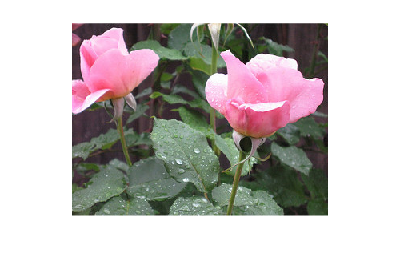

imgs = imageDatastore("check\");

inputSZ = [224 224];
preImg = augmentedImageDatastore(inputSZ, imgs);
pred = classify(flowernet, preImg);

% select a images
pth = imgs.Files(14);
indx = string(imgs.Files) == (pth);
imshow(imread(string(pth)));

pred(indx)

ans = categorical
     roses 
